clc
clear all

PowerIndices = [1,2,3,4]

PowerIndices =      1     2     3     4


TX_Categories = categorical({'Triangulation','WKNN-3','WKNN-4','WKNN-5'});



Noiseless = readtable("Noiseless.xlsx")

Noiseless = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       0.5089        0.0943    0.1118    0.0894
    {'TX_-30'}       1.1071        0.1368     0.121    0.1386
    {'TX_-35'}       1.3364        1.2088    1.2308    1.2083
    {'TX_-40'}       0.4696        2.1024    2.1053    2.1024


NoiselessPCTError = Noiseless

NoiselessPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       0.5089        0.0943    0.1118    0.0894
    {'TX_-30'}       1.1071        0.1368     0.121    0.1386
    {'TX_-35'}       1.3364        1.2088    1.2308    1.2083
    {'TX_-40'}       0.4696        2.1024    2.1053    2.1024


NoiselessPCTError{:,2:5} = (Noiseless{:,2:5}/7.071)*100

NoiselessPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}        7.197        1.3336    1.5811    1.2643
    {'TX_-30'}       15.657        1.9347    1.7112    1.9601
    {'TX_-35'}       18.899        17.095    17.406    17.088
    {'TX_-40'}       6.6412        29.733    29.774    29.733


NoiselessPCTError_Arr = NoiselessPCTError{:,2:5}

NoiselessPCTError_Arr =     7.1970    1.3336    1.5811    1.2643
   15.6569    1.9347    1.7112    1.9601
   18.8994   17.0952   17.4063   17.0881
    6.6412   29.7327   29.7737   29.7327


plot(PowerIndices, NoiselessPCTError_Arr, 'LineStyle',"-", 'LineWidth',1, 'Marker',"*")



Noisy = readtable("Noisy.xlsx")

Noisy = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}          NaN        0.1528    0.1319    0.1406
    {'TX_-30'}       1.1647        0.5711    0.5754    0.5682
    {'TX_-35'}       1.3028        0.6914    0.6754    0.6393
    {'TX_-40'}       0.4661        0.7643     0.767    0.7476


NoisyPCTError = Noisy

NoisyPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}          NaN        0.1528    0.1319    0.1406
    {'TX_-30'}       1.1647        0.5711    0.5754    0.5682
    {'TX_-35'}       1.3028        0.6914    0.6754    0.6393
    {'TX_-40'}       0.4661        0.7643     0.767    0.7476


NoisyPCTError{:,2:5} = (Noisy{:,2:5}/7.071)*100

NoisyPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}          NaN        2.1609    1.8654    1.9884
    {'TX_-30'}       16.472        8.0767    8.1375    8.0356
    {'TX_-35'}       18.425         9.778    9.5517    9.0412
    {'TX_-40'}       6.5917        10.809    10.847    10.573


NoisyPCTError_Arr = NoisyPCTError{:,2:5}

NoisyPCTError_Arr =        NaN    2.1609    1.8654    1.9884
   16.4715    8.0767    8.1375    8.0356
   18.4246    9.7780    9.5517    9.0412
    6.5917   10.8089   10.8471   10.5728


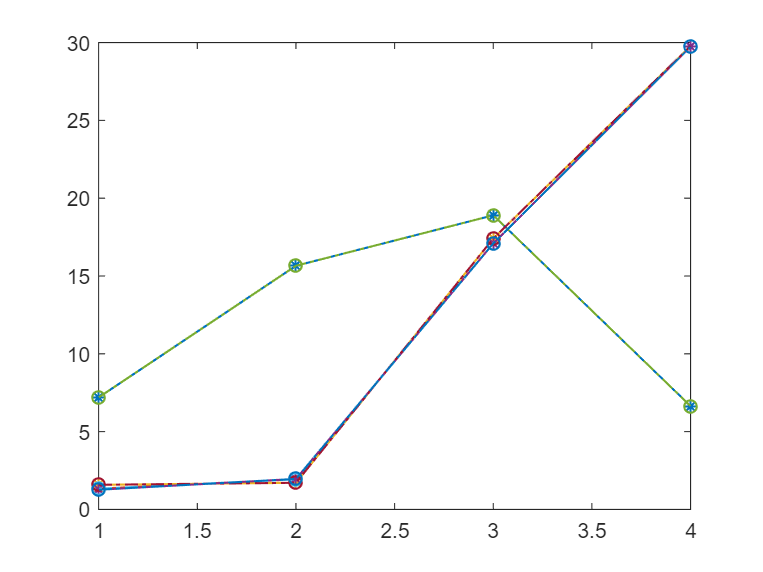

hold on
plot(PowerIndices, NoiselessPCTError_Arr, 'LineStyle',"-.", 'LineWidth',1, 'Marker',"o")

hold off

BARData1 = [NoiselessPCTError_Arr(1,1),NoisyPCTError_Arr(1,1);
                NoiselessPCTError_Arr(1,2),NoisyPCTError_Arr(1,2);
                    NoiselessPCTError_Arr(1,3),NoisyPCTError_Arr(1,3);
                      NoiselessPCTError_Arr(1,4),NoisyPCTError_Arr(1,4)]

BARData1 =     7.1970       NaN
    1.3336    2.1609
    1.5811    1.8654
    1.2643    1.9884


b1 = bar(TX_Categories,BARData1)

b1 =   1×2 Bar array:

    Bar    Bar


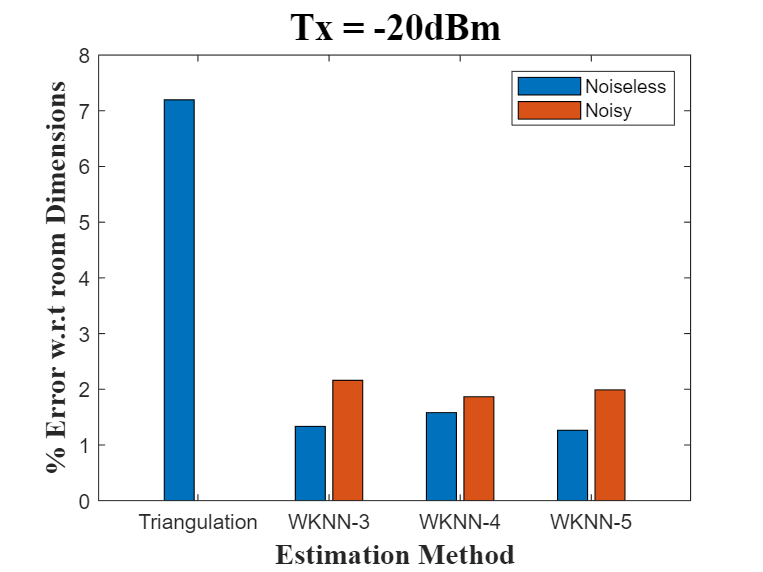

title('Tx = -20dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})


BARData2 = [NoiselessPCTError_Arr(2,1),NoisyPCTError_Arr(2,1);
                NoiselessPCTError_Arr(2,2),NoisyPCTError_Arr(2,2);
                    NoiselessPCTError_Arr(2,3),NoisyPCTError_Arr(2,3);
                      NoiselessPCTError_Arr(2,4),NoisyPCTError_Arr(2,4)]

BARData2 =    15.6569   16.4715
    1.9347    8.0767
    1.7112    8.1375
    1.9601    8.0356


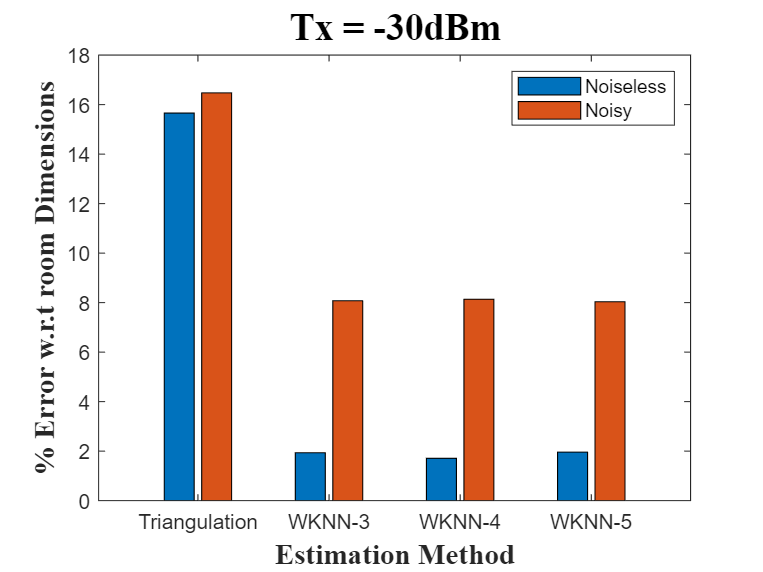


bar(TX_Categories,BARData2)
title('Tx = -30dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})


BARData3 = [NoiselessPCTError_Arr(3,1),NoisyPCTError_Arr(3,1);
                NoiselessPCTError_Arr(3,2),NoisyPCTError_Arr(3,2);
                    NoiselessPCTError_Arr(3,3),NoisyPCTError_Arr(3,3);
                      NoiselessPCTError_Arr(3,4),NoisyPCTError_Arr(3,4)]    

BARData3 =    18.8994   18.4246
   17.0952    9.7780
   17.4063    9.5517
   17.0881    9.0412


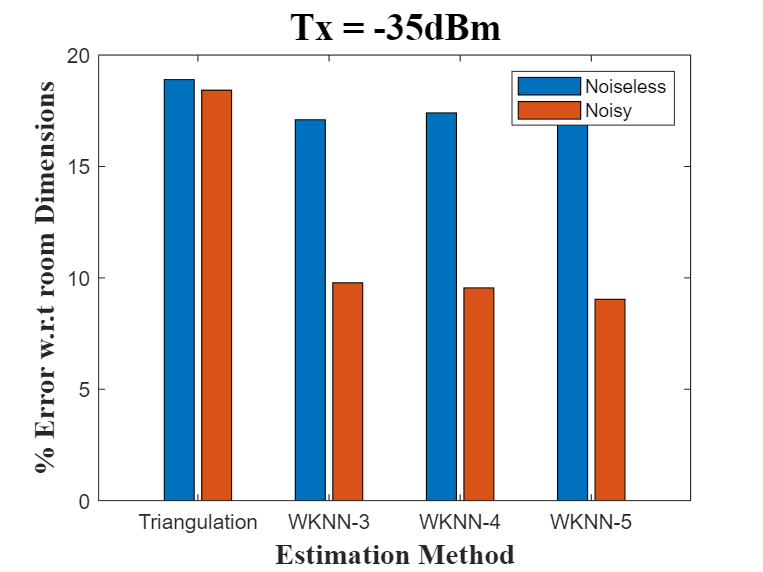

bar(TX_Categories,BARData3)
title('Tx = -35dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})


BARData4 = [NoiselessPCTError_Arr(4,1),NoisyPCTError_Arr(4,1);
                NoiselessPCTError_Arr(4,2),NoisyPCTError_Arr(4,2);
                    NoiselessPCTError_Arr(4,3),NoisyPCTError_Arr(4,3);
                      NoiselessPCTError_Arr(4,4),NoisyPCTError_Arr(4,4)]    

BARData4 =     6.6412    6.5917
   29.7327   10.8089
   29.7737   10.8471
   29.7327   10.5728


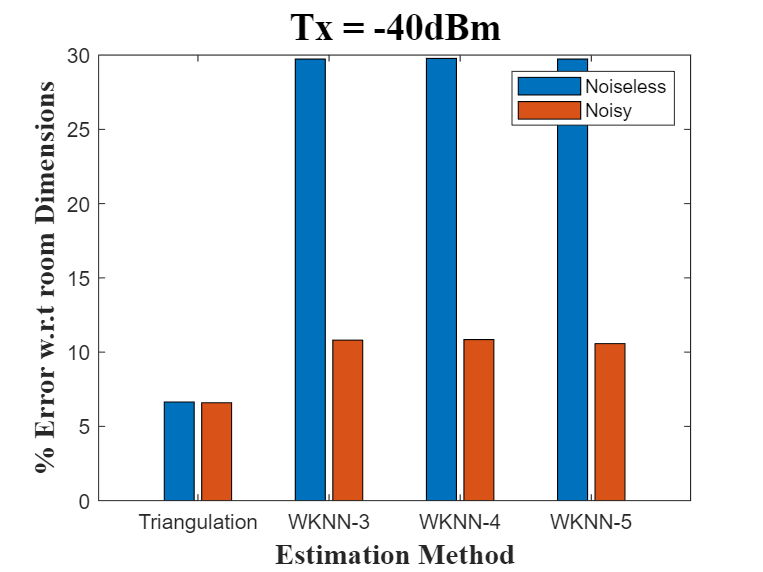

bar(TX_Categories,BARData4)
title('Tx = -40dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})